% Add path
addpath(genpath('.\Motion'));
addpath(genpath('.\Registration'));
addpath(genpath('.\SVD'));
addpath(genpath('.\KeyPoints'));

clear;
clc;

% Params
dataPath = 'C:\Users\Yaolab\Box\6monthVs.12month\Cases\CARSH_00177\11-24-2020\';
motionDataCSVFilePath   = [dataPath, 'Motion_csv\7.csv'];       % Motion data path
skullGeomagicMarkersPath = [dataPath, 'GeomagicFiles\Skull_Markers_Coordinates.csv'];
titleStr                = 'Maximum open and close';             % Name of oral task

% Read motion data from the CSV file
m_motionData = loadMotionCSVData(motionDataCSVFilePath);

Frame: missing 0 out of 4173 data.
TypeNameTimeSeconds: missing 0 out of 4173 data.
RigidBodyMandibleRotationX: missing 410 out of 4173 data.
RigidBodyMandibleRotationY: missing 410 out of 4173 data.
RigidBodyMandibleRotationZ: missing 410 out of 4173 data.
RigidBodyMandibleRotationW: missing 410 out of 4173 data.
RigidBodyMandiblePositionX: missing 410 out of 4173 data.
RigidBodyMandiblePositionY: missing 410 out of 4173 data.
RigidBodyMandiblePositionZ: missing 410 out of 4173 data.
RigidBodyMandibleMeanMarkerError: missing 410 out of 4173 data.
RigidBodyMarkerMandibleMarker1PositionX: missing 410 out of 4173 data.
RigidBodyMarkerMandibleMarker1PositionY: missing 410 out of 4173 data.
RigidBodyMarkerMandibleMarker1PositionZ: missing 410 out of 4173 data.
RigidBodyMarkerMandibleMarker1MarkerQuality: missing 410 out of 4173 data.
RigidBodyMarkerMandibleMarker2PositionX: missing 410 out of 4173 data.
RigidBodyMarkerMandibleMarker2PositionY: missing 410 out of 4173 data.
RigidBodyMarkerM


% Read skull markers position in CBCT 
m_skullGeomagicMarkers = loadSkullGeomagicPoints(skullGeomagicMarkersPath);

% Reorder skull markers order based on relative distance relationship of markers
m_motionData = reorderSkullMarkers(m_motionData, m_skullGeomagicMarkers);

% Get mandible markers position based on skull markers in CBCT, skull
% markers in motion, mandible markers in motion
m_mandibleGeomagicPoints = registerMandibleBySkull(m_motionData, m_skullGeomagicMarkers);

% Fix skull position based on skull markers in CBCT
m_motionData = fixSkullMarkers(m_motionData, m_skullGeomagicMarkers);

Frame 1, Alignment accuracy: 14.069808
Frame 2, Alignment accuracy: 14.069808
Frame 3, Alignment accuracy: 14.069807
Frame 4, Alignment accuracy: 14.069809
Frame 5, Alignment accuracy: 14.069805
Frame 6, Alignment accuracy: 14.069806
Frame 7, Alignment accuracy: 14.069807
Frame 8, Alignment accuracy: 14.069804
Frame 9, Alignment accuracy: 14.069805
Frame 10, Alignment accuracy: 14.069806
Frame 11, Alignment accuracy: 14.069806
Frame 12, Alignment accuracy: 14.069806
Frame 13, Alignment accuracy: 14.069808
Frame 14, Alignment accuracy: 14.069811
Frame 15, Alignment accuracy: 14.069808
Frame 16, Alignment accuracy: 14.069807
Frame 17, Alignment accuracy: 14.069808
Frame 18, Alignment accuracy: 14.069809
Frame 19, Alignment accuracy: 14.069807
Frame 20, Alignment accuracy: 14.069806
Frame 21, Alignment accuracy: 14.069806
Frame 22, Alignment accuracy: 14.069807
Frame 23, Alignment accuracy: 14.069807
Frame 24, Alignment accuracy: 14.069809
Frame 25, Alignment accuracy: 14.069807
Frame 26,


% Filter motion data
m_motionData = filterMotionData(m_motionData);

% Smooth motion data
m_motionData = smoothMotionData(m_motionData);

% viewMotionData(m_motionData)

% Load key points to track trajectory
skullGeomagicPointsPath    = [dataPath, 'GeomagicFiles\Skull_Points_Coordinates.csv'];
mandibleGeomagicPointsPath = [dataPath, 'GeomagicFiles\Mandible_Points_Coordinates.csv'];

m_keyGeomagicPoints = loadKeyGeomagicPoints(skullGeomagicPointsPath, mandibleGeomagicPointsPath);
m_keyGeomagicPoints = computeKeyPointsTrajectory(m_motionData, m_keyGeomagicPoints);

Frame 2, Alignment accuracy: 0.000000
Frame 2, Alignment accuracy: 0.000001
Frame 3, Alignment accuracy: 0.000000
Frame 3, Alignment accuracy: 0.000001
Frame 4, Alignment accuracy: 0.000000
Frame 4, Alignment accuracy: 0.000002
Frame 5, Alignment accuracy: 0.000000
Frame 5, Alignment accuracy: 0.000002
Frame 6, Alignment accuracy: 0.000000
Frame 6, Alignment accuracy: 0.000002
Frame 7, Alignment accuracy: 0.000000
Frame 7, Alignment accuracy: 0.000002
Frame 8, Alignment accuracy: 0.000000
Frame 8, Alignment accuracy: 0.000002
Frame 9, Alignment accuracy: 0.000000
Frame 9, Alignment accuracy: 0.000002
Frame 10, Alignment accuracy: 0.000000
Frame 10, Alignment accuracy: 0.000002
Frame 11, Alignment accuracy: 0.000000
Frame 11, Alignment accuracy: 0.000002
Frame 12, Alignment accuracy: 0.000000
Frame 12, Alignment accuracy: 0.000002
Frame 13, Alignment accuracy: 0.000000
Frame 13, Alignment accuracy: 0.000003
Frame 14, Alignment accuracy: 0.000000
Frame 14, Alignment accuracy: 0.000003
Fr

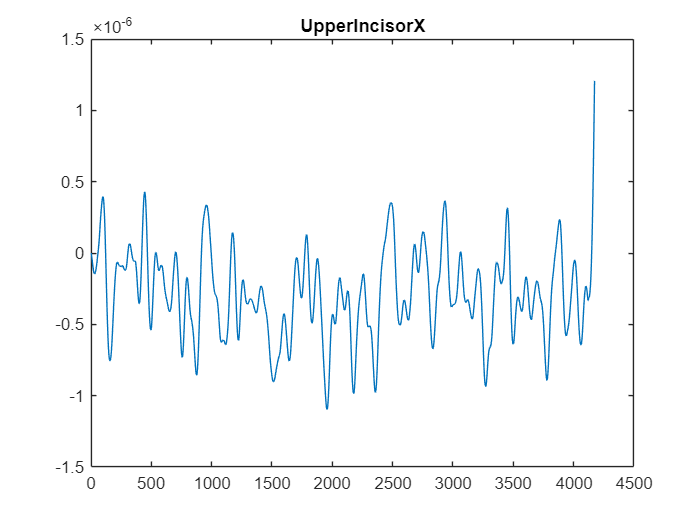

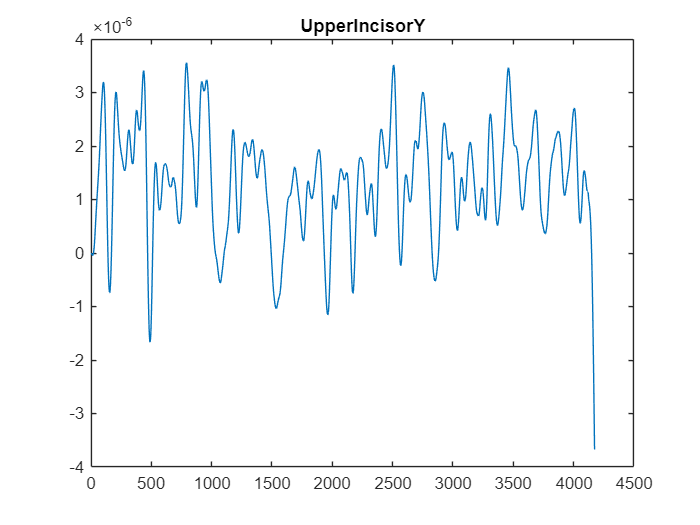

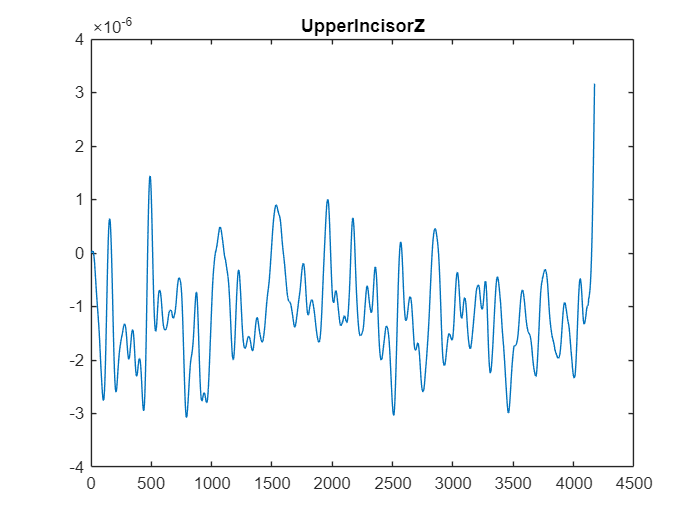

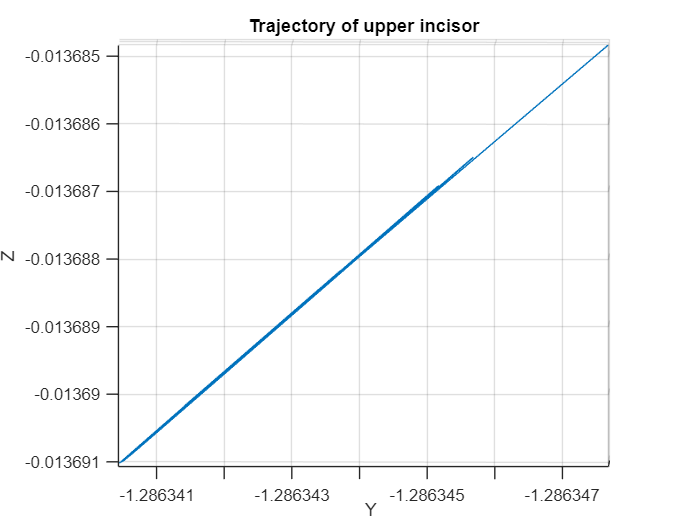

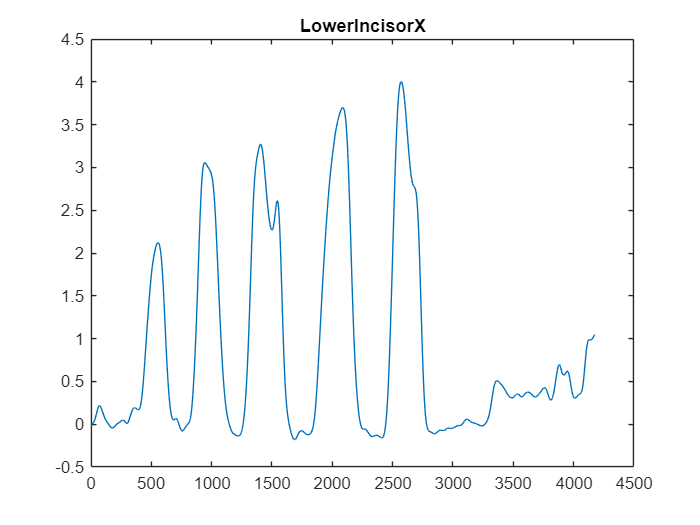

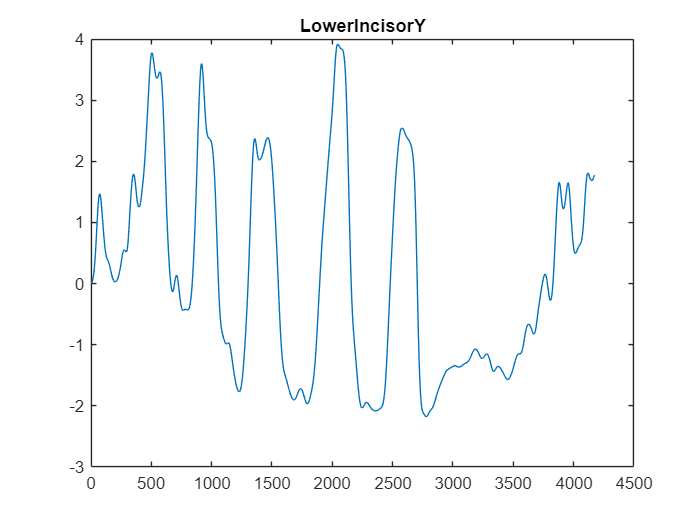

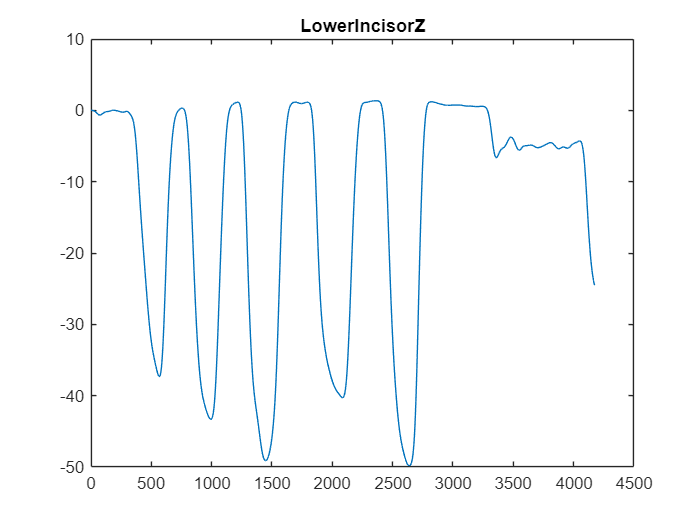

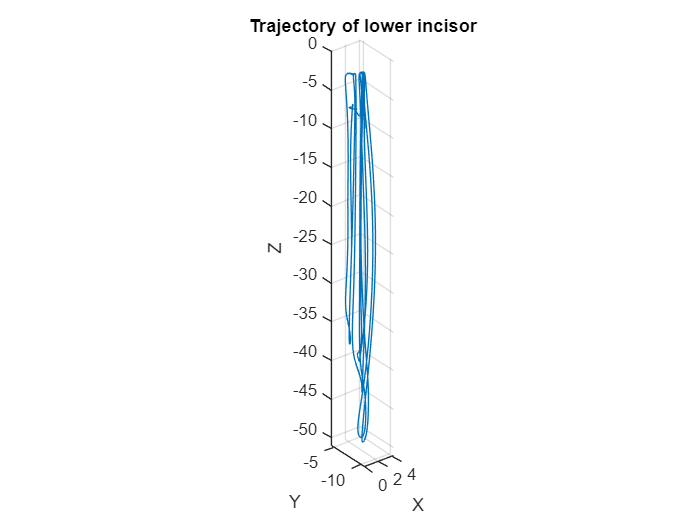


viewKeyPointsData(m_keyGeomagicPoints);

% Remove path
rmpath(genpath('.\Motion'));
rmpath(genpath('.\Registration'));
rmpath(genpath('.\SVD'));
rmpath(genpath('.\KeyPoints'));